clear 
num_c = 20;  % number of cars 

% Initial Conditions 
% Note: The index of the car corresponds to the order of the car. (Ex: Car 1
% is in the first element of the vector)
pos_0 = linspace(200, 0, num_c); % Initial position of cars.
vel_0 = zeros(1,num_c); % Initial velocity of cars. 
acc_0 = zeros(1,num_c); % Inital acceleration of cars.

% Characteristic of cars and road. 
lengths = ones(1,num_c)*5; % Length of cars. 
gamma = 0.6; % Speed difference sensitivity. 
x_destination = 2000; % Destination.
maxLane = 3;
b_safe = 3;
delta_a = 0.1;
a_bias = 0.3;

% Parameters for Numerical Integration
tstep = .01;
t_final = 100;
numsteps = round(t_final/tstep);

% Default initialize an array and set parameters for the vehicles. 
vehiclesInOrder(1:num_c) = Vehicle(); 
for i = 1:num_c
    vehiclesInOrder(i) = Vehicle(i, pos_0(i), vel_0(i), acc_0(i), floor(rand*3) + 1, lengths(i), false);
end
% vehiclesInOrder(num_c) = Vehicle(num_c, pos_0(num_c), vel_0(num_c), acc_0(num_c), 2, lengths(num_c), false, 0.65, 40, 15, 1.5, 1.4, 3);
% 
% Closed Lane
tlArr = [Vehicle(num_c + 1, 2000, 0, 0, 1, 1100, true), Vehicle(num_c + 1, 2000, 0, 0, 2, 1000, true)];
num_c = num_c + length(tlArr);
vehiclesInOrder = [vehiclesInOrder, tlArr];
vehiclesInOrder = Vehicle.sortCars(vehiclesInOrder);

% Create array to store time, position, velocity, acceleration, and gap.
tvals = linspace(0, t_final, numsteps);
xvals = zeros(numsteps, num_c);
vvals = zeros(numsteps, num_c);
avals = zeros(numsteps, num_c);
gvals = zeros(numsteps, num_c);
lanevals = zeros(numsteps, num_c);


for t = 1:numsteps
    for i = num_c:-1:1 % Loop through the car starting with the last car.
        if ~vehiclesInOrder(i).isVirtual
            laneNum = vehiclesInOrder(i).lane;
            [v_l, s, ~, ~] = Vehicle.findGaps(vehiclesInOrder, i, laneNum, x_destination);

            % Compute gap and state variables.
            newstate = vehiclesInOrder(i).timestep(s, v_l, tstep, gamma);
            v_num = vehiclesInOrder(i).number;
            gvals(t, v_num) = s;
            xvals(t, v_num) = newstate(1);
            vvals(t, v_num) = newstate(2);
            avals(t, v_num) = newstate(3);
            lanevals(t, v_num) = vehiclesInOrder(i).lane;
            
            %lane change
            newlane = vehiclesInOrder(i).changeLane(i, vehiclesInOrder, maxLane, b_safe, delta_a, a_bias, gamma, x_destination);
            
        else
            %It is a traffic light
            v_num = vehiclesInOrder(i).number;
            xvals(t, v_num) = vehiclesInOrder(i).state(1);

        end
              
    end
         
    vehiclesInOrder = Vehicle.sortCars(vehiclesInOrder);
end

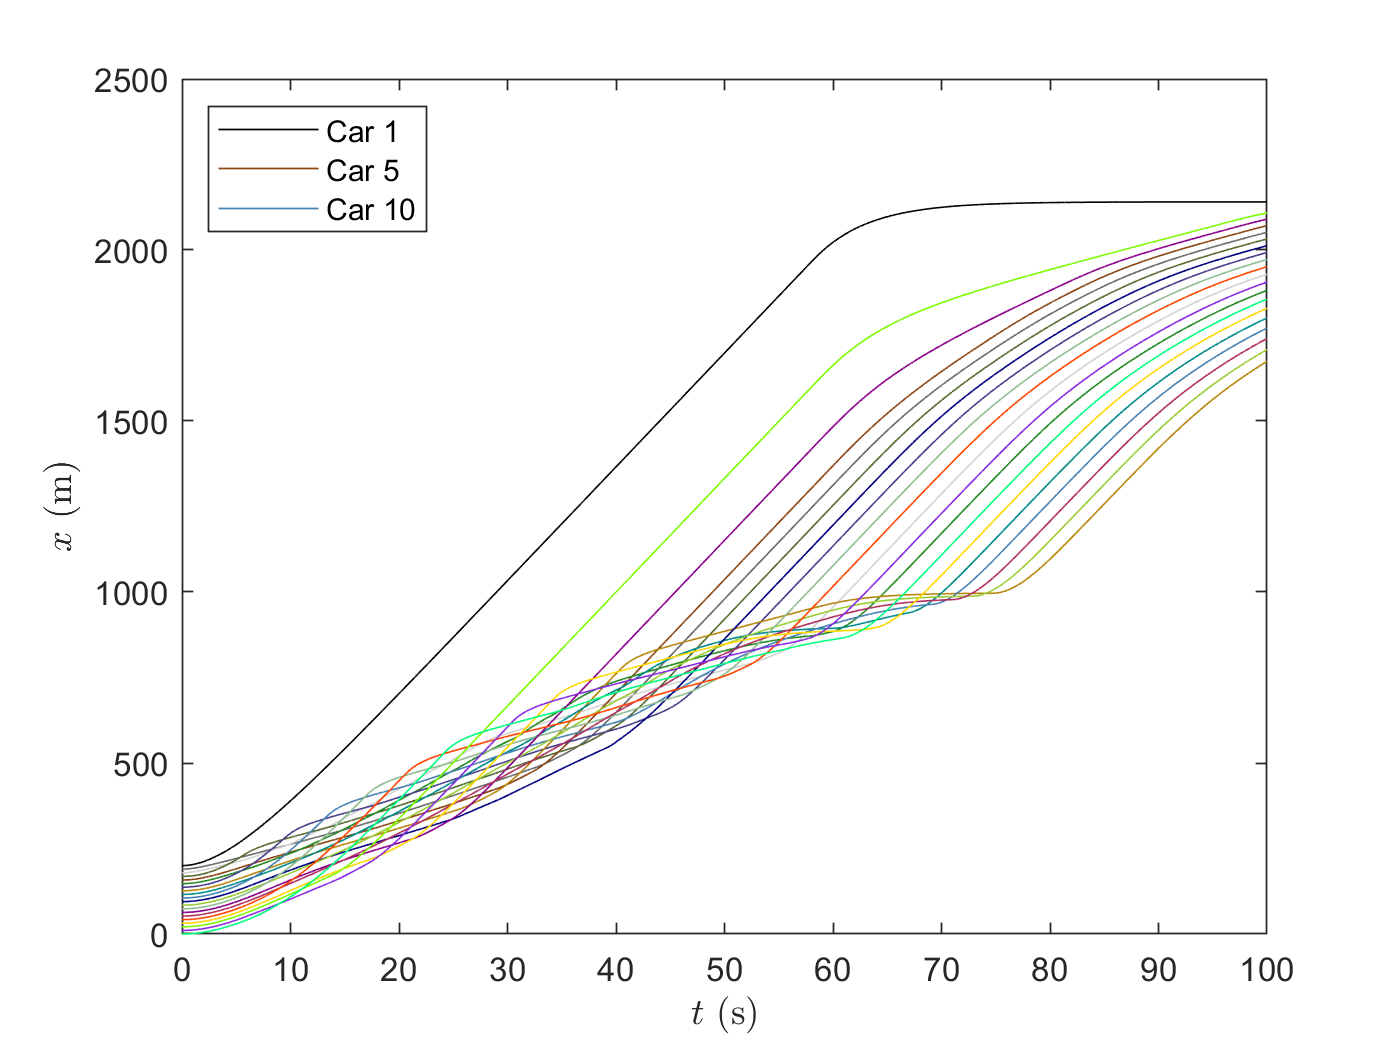

cmap = (1/256) .*[0, 0, 0;
        105, 105, 105;
        211, 211, 211;
        85, 107, 47;
        139, 69, 19;
        34, 139, 34;
        72, 61, 139;
        184, 134, 11;
        0, 139, 139;
        70, 130, 180;
        0, 0, 128;
        154, 205, 50;
        143, 188, 143;
        139, 0, 139;
        176, 48, 96;
        255, 69, 0;
        255, 215, 0;
        124, 252, 0;
        138, 43, 226;
        0, 255, 127;
        220, 20, 60;
        0, 255, 255;
        0, 0, 255;
        255, 0, 255;
        30, 144, 255;
        240, 230, 140;
        144, 238, 144;
        255, 20, 147;
        255, 160, 122;
        238, 130, 238];
colorspec = num2cell(cmap,2);

% Graph position versus time. 
for i = 1:num_c-2
    h(i) = plot(tvals, xvals(:,i), 'Color', colorspec{i});
    hold on;
end
legend([h(1) h(5) h(10)], 'Car 1', 'Car 5', 'Car 10', 'Location', 'northwest');
xlabel("$t$ (s)",'Interpreter',"latex")
ylabel("$x$ (m)", 'Interpreter',"latex")

hold off;

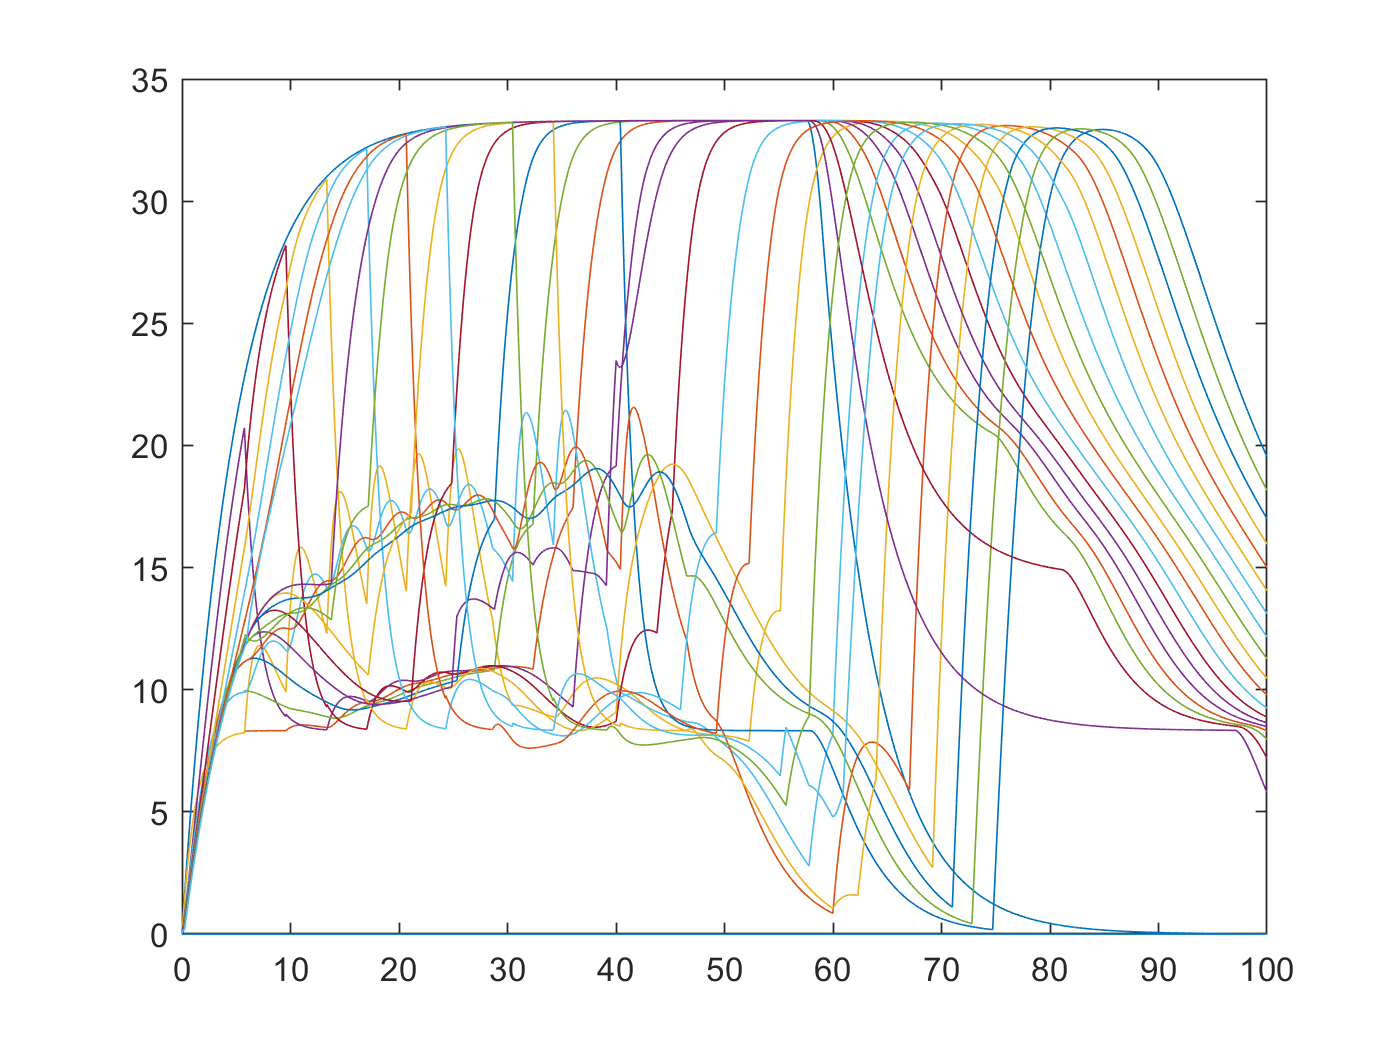

% Graph velocity versus time.
for i = 1:num_c
    plot(tvals, vvals(:,i))
    hold on;
end
hold off;

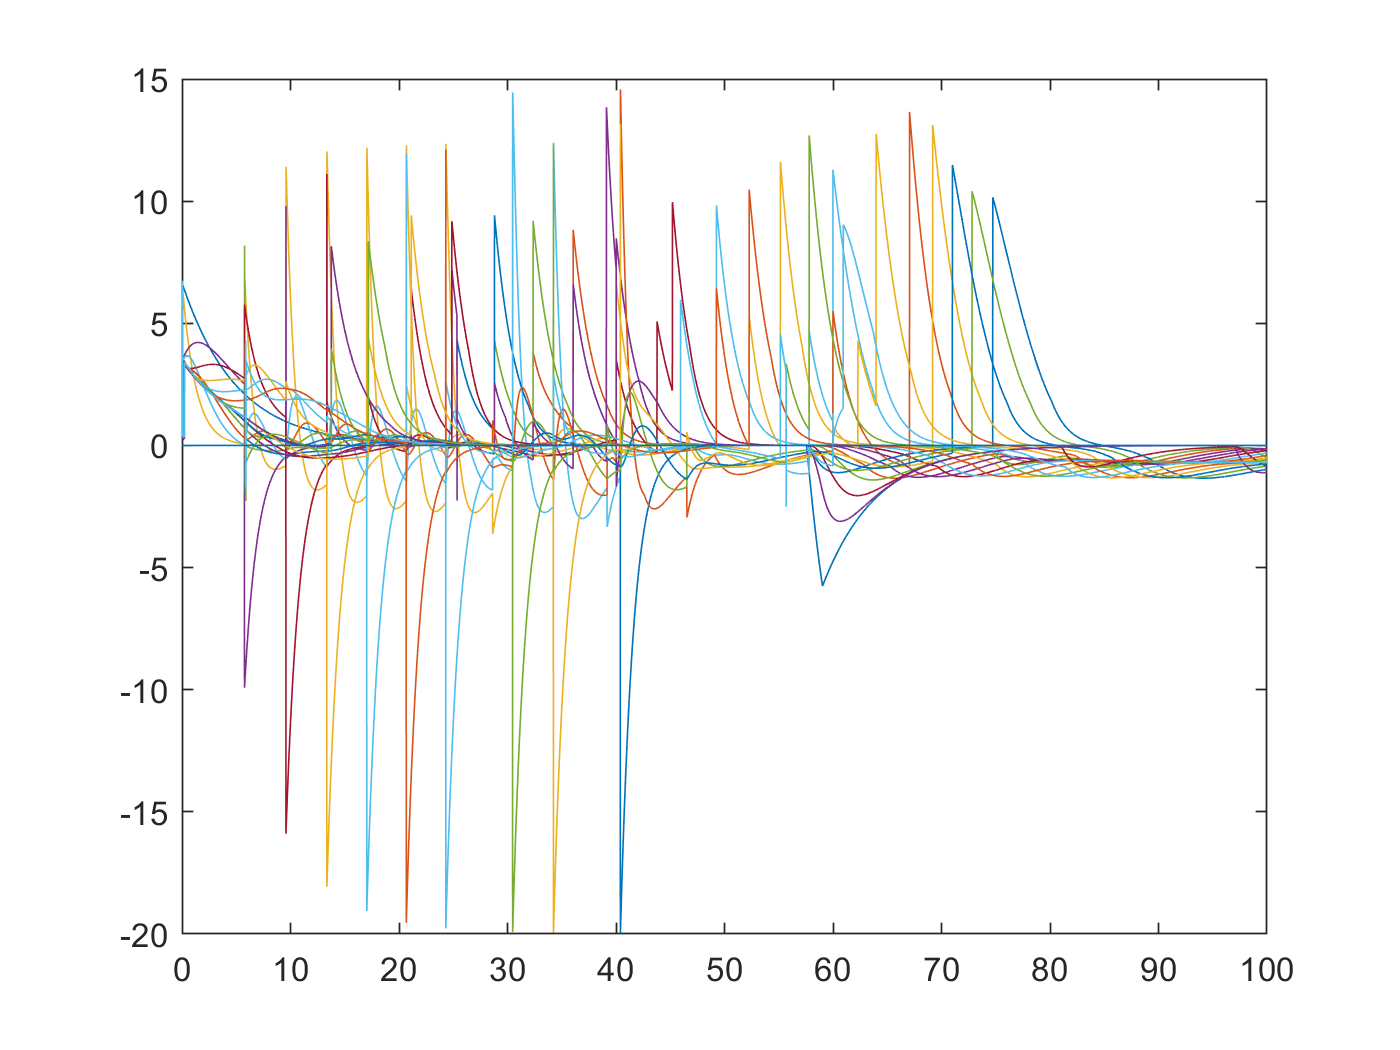

% Graph acceleration versus time.
for i = 1:num_c
    plot(tvals, avals(:,i))
    hold on;
end
hold off;

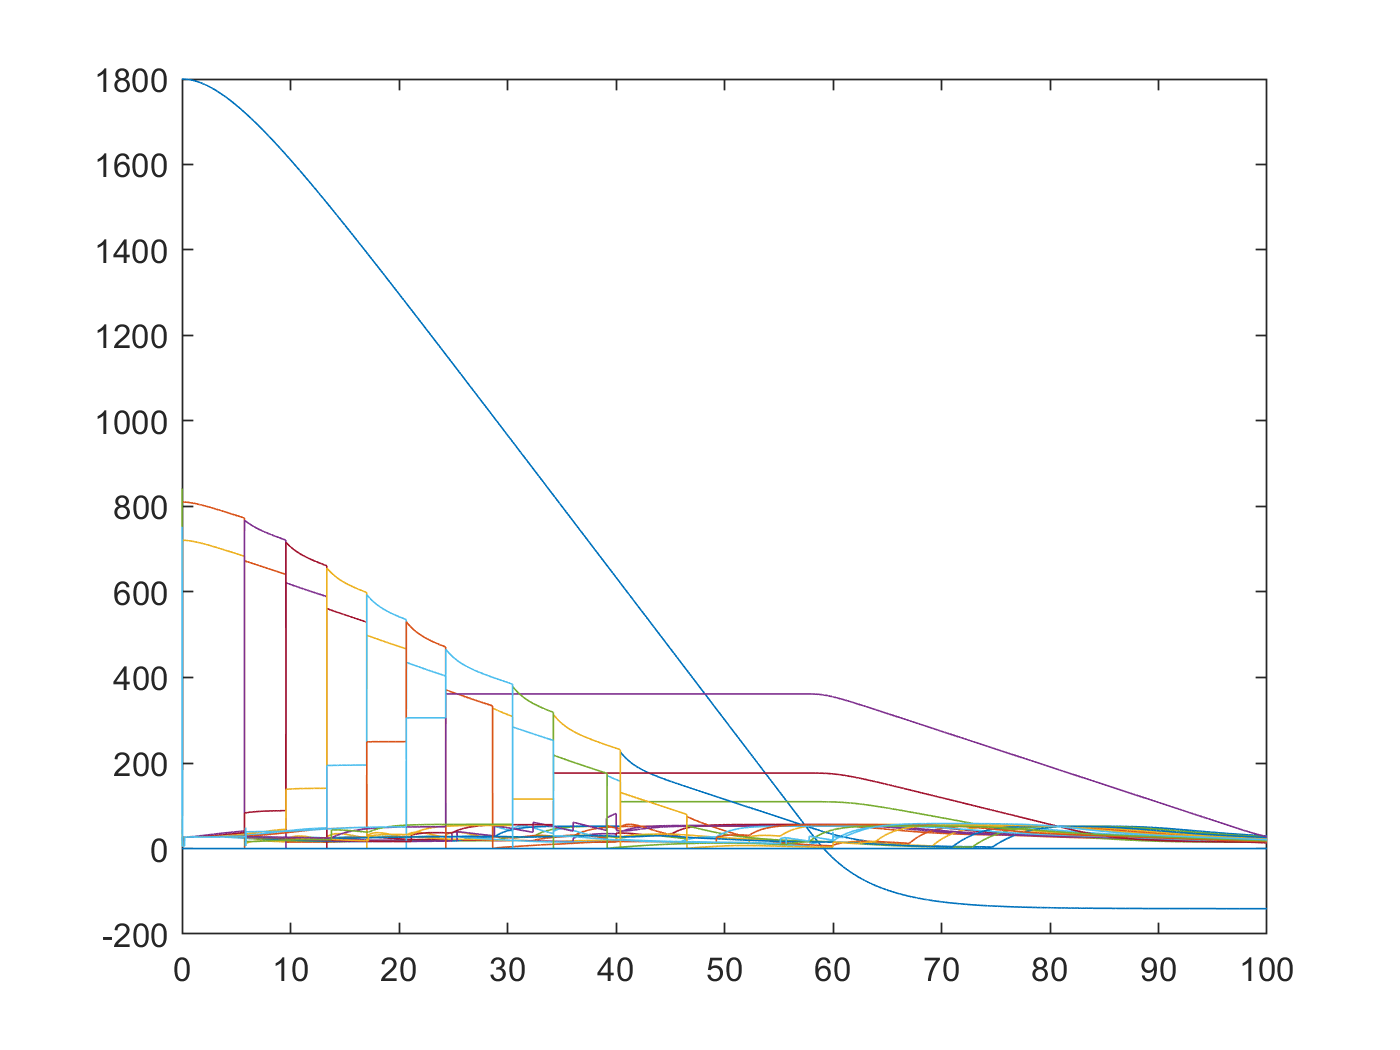

% Graph gap versus time.
for i = 1:num_c
    plot(tvals, gvals(:,i))
    hold on;
end
hold off

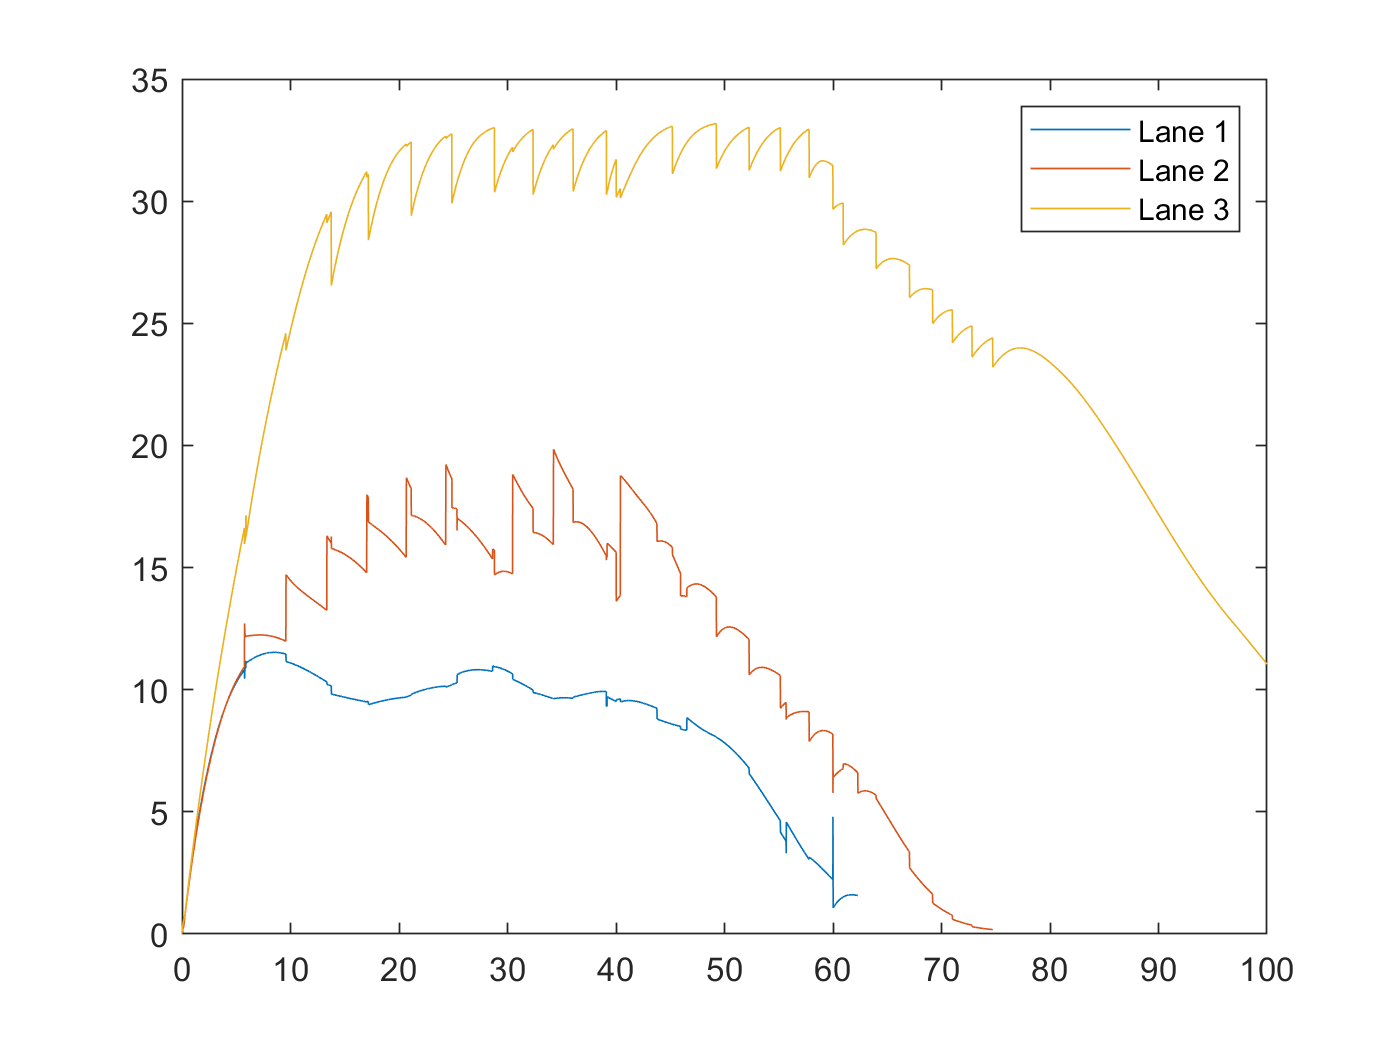

% Finding mean lane speed 
meanSpeedPerLane = zeros(size(tvals,2),maxLane);
for i=1:size(tvals,2)
    for j=1:maxLane
        val = 0;
        num = 0;
        for k=1:num_c
            if lanevals(i,k) == j
                num = num + 1;
                val = val + vvals(i,k);
            end
        end
        meanSpeedPerLane(i,j) = val / num;
    end
end

% Graph mean lane speed versus time
for i = 1:maxLane
    plot(tvals, meanSpeedPerLane(:,i))
    hold on;
end
legend("Lane 1", "Lane 2", "Lane 3")
hold off;

% Calculate flow rate. 
time = 2:2:t_final;
delta_t = 2;
delta_x = linspace(0,x_destination,1000);
flow = zeros(length(time),length(delta_x));
for i=1:length(time)-1
    for j=1:length(delta_x)
        counter = 0;
        for k=1:size(xvals,2)
            posOfInterest = xvals((time(i)/tstep):((time(i)/tstep) + (delta_t/tstep)),k);  % normalize the time values
            for l=1:length(posOfInterest)-1
                if posOfInterest(l) < delta_x(j) && posOfInterest(l+1) > delta_x(j)
                    counter = counter + 1;
                end
            end
            flow(i,j) = counter;
        end
    end
end
dist = linspace(0,x_destination,100);
flow = transpose(flow);
colormap('hot');         % set colormap

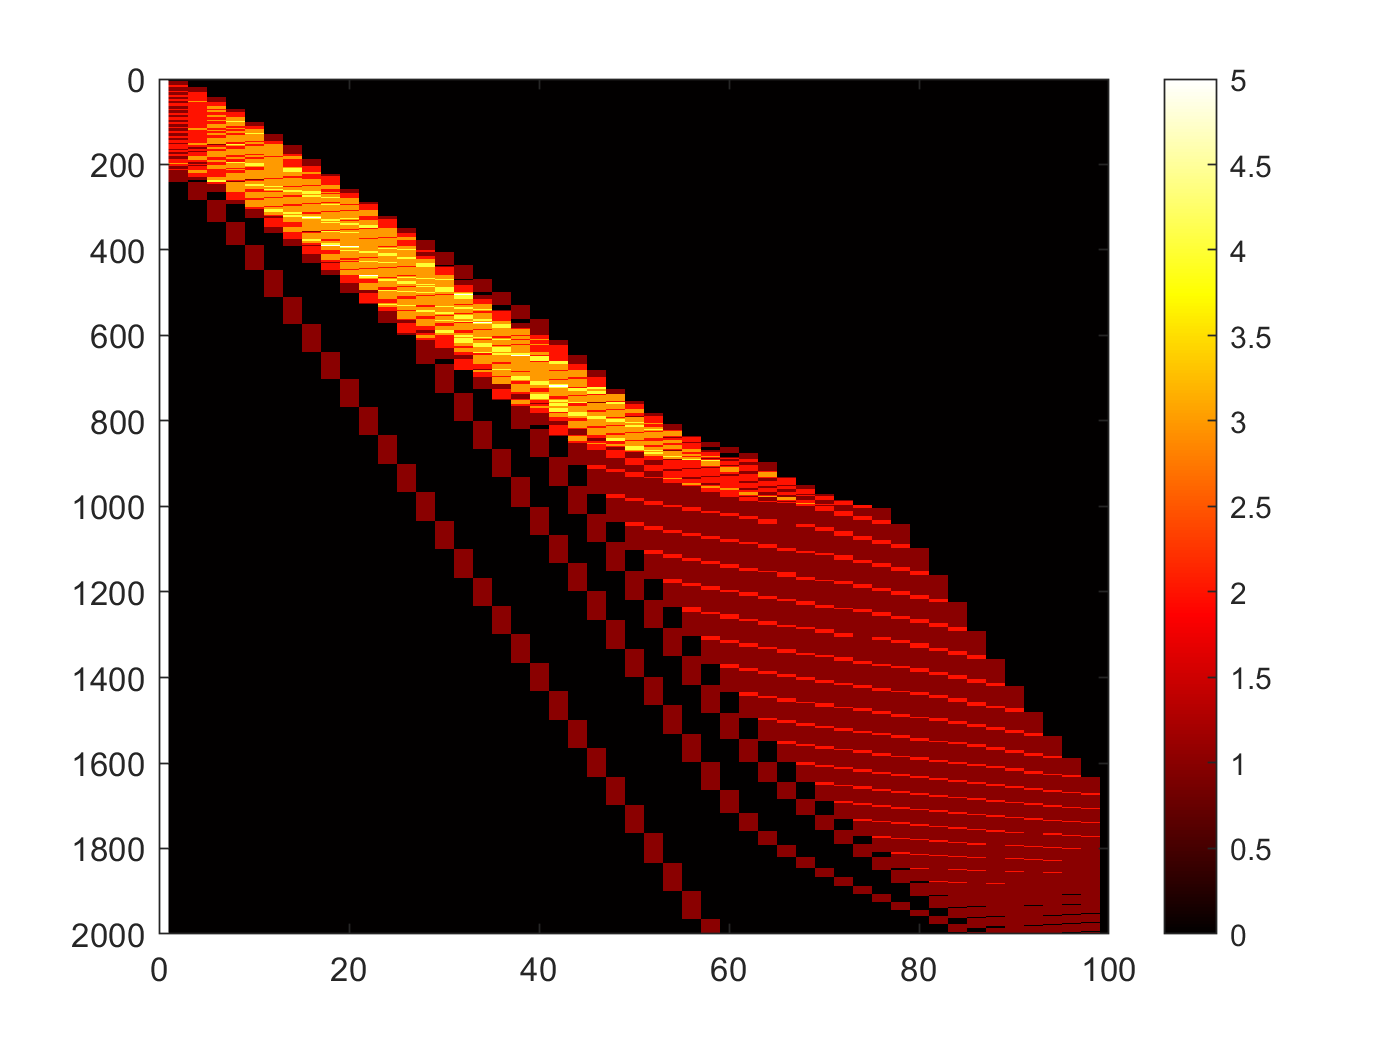

imagesc(time,dist,flow);        % draw image and scale colormap to values range
xlim([0 t_final]);
ylim([0 x_destination]);
colorbar;

% Calculate Density
time = 1:(t_final/tstep);
time = time./100;
delta_x = linspace(0,x_destination,100);
density = zeros(length(time),length(delta_x) - 1);
for i=1:(t_final/tstep)
    for j=1:(length(delta_x) - 1)
        carDensity = length(find(xvals(i,:) > delta_x(j) & xvals(i,:) < delta_x(j+1)));
        density(i,j) = carDensity;
    end
end
dist = linspace(0,x_destination,length(delta_x) - 1);
density = transpose(density);
colormap('hot');         % set colormap

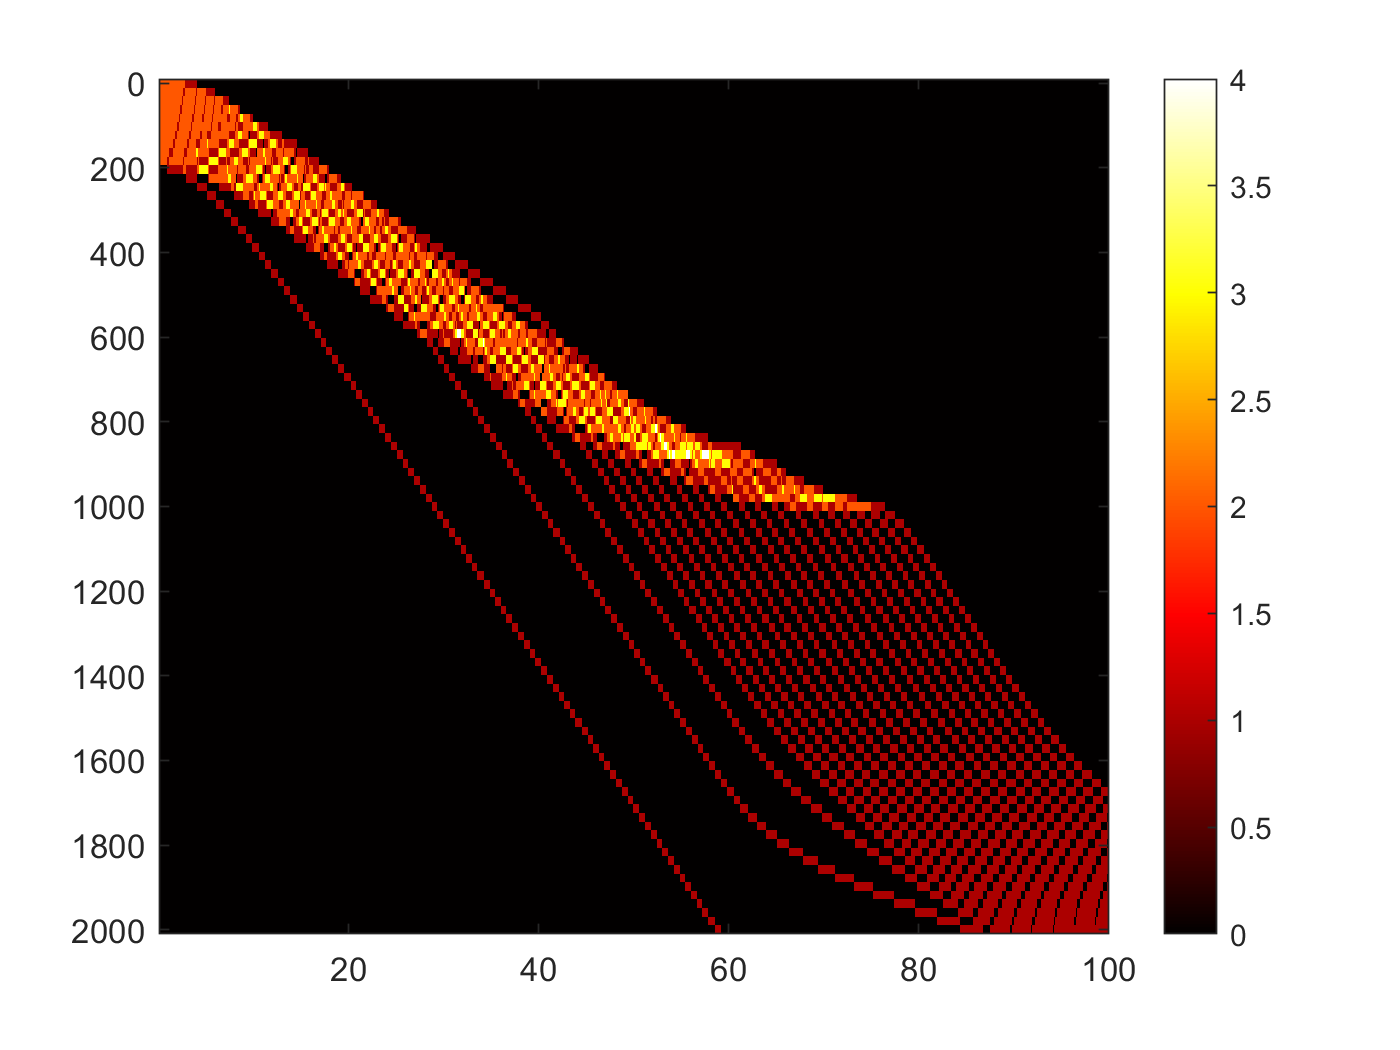

imagesc(time,dist,density);        % draw image and scale colormap to values range
colorbar;